# Part 1

## Change of Variable

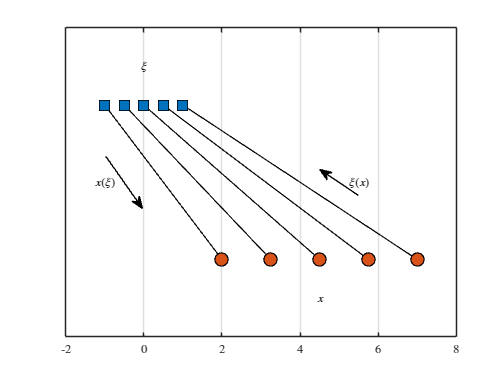

clear
close all

N = 5;
from_domain = [-1, 1];
to_domain = [2, 7];

from_values = linspace( from_domain(1), from_domain(2), N );
to_values = ChangeOfVariable( from_values, from_domain, to_domain );

hf = figure;
hold on
ax = gca;
ax.YTick = [];
ax.XLim = [ min( [from_domain, to_domain] ) - 1,  max( [from_domain, to_domain] ) + 1 ];
ax.YLim = [-0.5, 1.5];
ax.XGrid = "on";

for n = 1 : N
    plot( [from_values(n) to_values(n)], [1 0], Color="k", LineWidth=1 )
end

scatter( from_values, ones( N, 1 ), Marker="s", MarkerFaceColor="flat", MarkerEdgeColor="k", SizeData=120, LineWidth=1, SeriesIndex=1 )
% scatter( [from_domain(1), from_domain(end)], ones(2,1), Marker="|", MarkerEdgeColor="k", LineWidth=2 )
text( mean( from_domain ), 1.25, "$\xi$", Interpreter="latex", HorizontalAlignment="center", VerticalAlignment="middle" )

scatter( to_values, zeros( N, 1 ), Marker="o", MarkerFaceColor="flat", MarkerEdgeColor="k", SizeData=120, LineWidth=1, SeriesIndex=2 )
% scatter( [to_values(1), to_values(end)], zeros(2,1), Marker="|", MarkerEdgeColor="k", LineWidth=2 )
text( mean( to_domain ), -0.25, "$x$", Interpreter="latex", HorizontalAlignment="center", VerticalAlignment="middle" )

scaled_arrow( ax, [mean( [from_domain(1), to_domain(1) ] ) - 1, 0.5], ( 1 - 0 ) / ( from_domain(1) - to_domain(1) ), 1 )
scaled_arrow( ax, [mean( [from_domain(end), to_domain(end)] ) + 1, 0.5], ( 1 - 0 ) / ( from_domain(end) - to_domain(end) ), -1 )
text( mean( [from_domain(1), to_domain(1) ] ) - 1.5, 0.5, "$x(\xi)$", Interpreter="latex", HorizontalAlignment="center", VerticalAlignment="middle" )
text( mean( [from_domain(end), to_domain(end)] ) + 1.5, 0.5, "$\xi(x)$", Interpreter="latex", HorizontalAlignment="center", VerticalAlignment="middle" )

## Change of Variable in a function

clear
close all

xi = sym( "xi", "real" );
from_domain = [-1, 1];
to_domain = [2, 7];
domain = [min( [from_domain, to_domain] ), max( [from_domain, to_domain] )]

domain =     -1     7


f(xi) = real( xi^xi )

$$f(xi) = \mathrm{real}\left(\xi^{\xi }\right)$$


x = ChangeOfVariable( xi, to_domain, from_domain )

$$x = \frac{2\,\xi }{5}-\frac{9}{5}$$

g = real( x^x )

$$g = \mathrm{real}\left({\left(\frac{2\,\xi }{5}-\frac{9}{5}\right)}^{\frac{2\,\xi }{5}-\frac{9}{5}}\right)$$

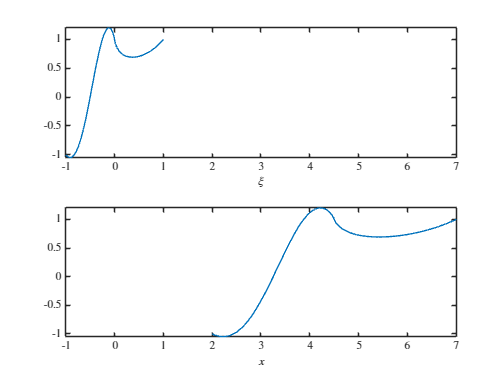


figure
ax(1) = subplot( 2, 1, 1 );
fplot( f, from_domain )
ax(1).XLim = domain;
xlabel( "$\xi$", Interpreter="latex" )

ax(2) = subplot( 2, 1, 2 );
fplot( g, to_domain )
ax(2).XLim = domain;
xlabel( "$x$", Interpreter="latex" )

## Polynomial Roots from Linear Algebra

clear
close all

x = sym( "x", "real" );
f = -1*x^4 + 4*x^2 + 1*x^1 - 1*x^0

$$f = -x^{4}+4\,x^{2}+x-1$$


C = CompanionMatrix( f )

$$C = \left[\begin{array}{cccc} 0 & 0 & 0 & -1\\ 1 & 0 & 0 & 1\\ 0 & 1 & 0 & 4\\ 0 & 0 & 1 & 0 \end{array}\right]$$

r = PolynomialRoots( f );
dr = real( double( r ) )

dr =    -1.7640
   -0.6938
    0.3963
    2.0615


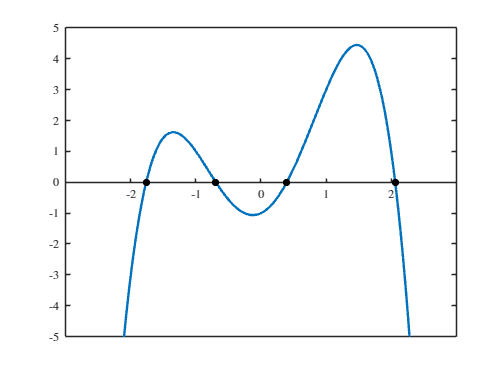


figure
hold on
fplot( f, [-3 3], LineWidth=2 )
scatter( dr, zeros( size( dr  ) ), MarkerFaceColor="k", MarkerEdgeColor="none" )

ax = gca;
ax.YLim = [-5 5];
ax.XAxisLocation = "origin";

## Polynomial Bases

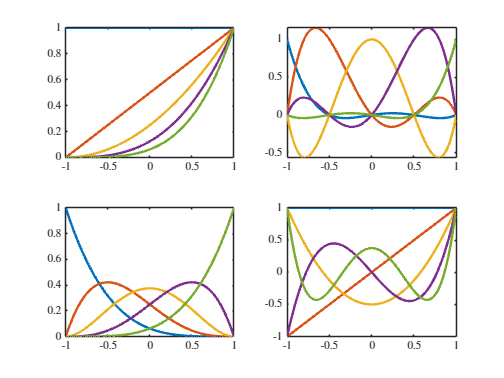

clear
close all

x = sym( "x", "real" );
domain = [-1, 1];
degree = 4;

figure
subplot( 2, 2, 1 )
fplot( PolynomialBasisFunction( "Monomial", degree, x, domain ), domain, LineWidth=2 );
subplot( 2, 2, 2 )
fplot( PolynomialBasisFunction( "Lagrange", degree, x, domain ), domain, LineWidth=2 );
subplot( 2, 2, 3 )
fplot( PolynomialBasisFunction( "Bernstein", degree, x, domain ), domain, LineWidth=2 );
subplot( 2, 2, 4 )
fplot( PolynomialBasisFunction( "Legendre", degree, x, domain ), domain, LineWidth=2 );

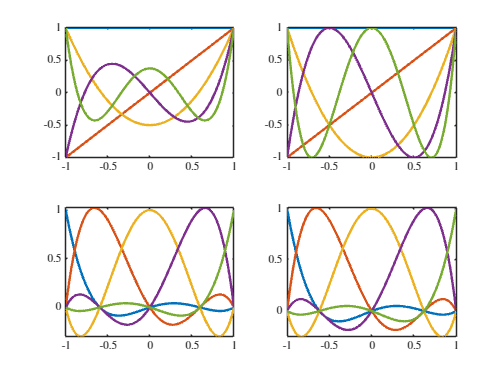


figure
subplot( 2, 2, 1 )
fplot( PolynomialBasisFunction( "Legendre", degree, x, domain ), domain, LineWidth=2 );
subplot( 2, 2, 2 )
fplot( PolynomialBasisFunction( "Chebyshev", degree, x, domain ), domain, LineWidth=2 );
subplot( 2, 2, 3 )
fplot( PolynomialBasisFunction( "Lagrange-Legendre", degree, x, domain ), domain, LineWidth=2 );
subplot( 2, 2, 4 )
fplot( PolynomialBasisFunction( "Lagrange-Chebyshev", degree, x, domain ), domain, LineWidth=2 );

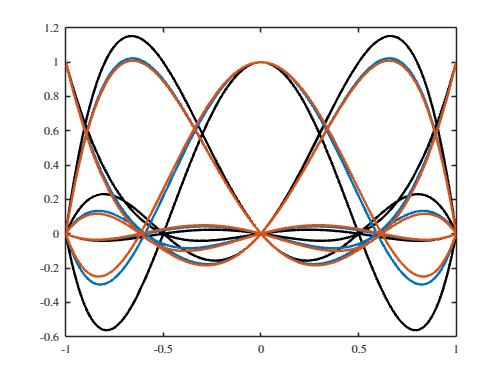


figure
hold on
fplot( PolynomialBasisFunction( "Lagrange", degree, x, domain ), domain, Color="k", LineWidth=2 );
fplot( PolynomialBasisFunction( "Lagrange-Legendre", degree, x, domain ), domain, SeriesIndex=1, LineWidth=2 );
fplot( PolynomialBasisFunction( "Lagrange-Chebyshev", degree, x, domain ), domain, SeriesIndex=2, LineWidth=2 );

## L2 Inner Product

clear
close all

x = sym( "x", "real" );
domain = [0, 1];

f = sin( pi*x )

$$f = \sin\left(\pi \,x\right)$$

g = -(2*x-1)^2 + 1

$$g = 1-{\left(2\,x-1\right)}^{2}$$


int( f*g, domain )

$$ans = \frac{16}{\pi^{3}}$$

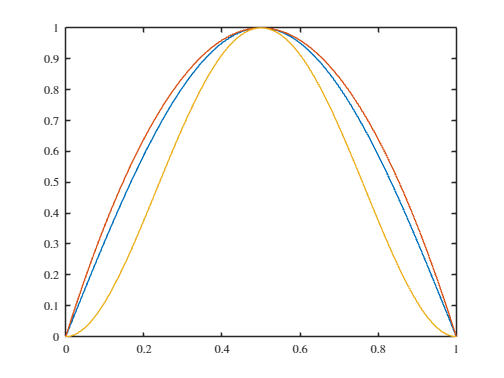


figure
hold on
fplot( f, domain )
fplot( g, domain )
fplot( f*g, domain )

## Polynomial Change of Basis

clear
close all

x = sym( "x", "real" );
domain = [0, 1];

f = -1*x^4 + 4*x^2 + 1*x^1 - 1*x^0

$$f = -x^{4}+4\,x^{2}+x-1$$

degree = polynomialDegree( f )

degree = 4

m_coeff = transpose( coeffs( f, "All" ) )

$$m\_coeff = \left[\begin{array}{c} -1\\ 0\\ 4\\ 1\\ -1 \end{array}\right]$$


M = MonomialBasis( degree, x, domain );
L = LagrangeBasis( degree, x, domain );
B = BernsteinBasis( degree, x, domain );
P = LegendreBasis( degree, x, domain );
T = ChebyshevBasis( degree, x, domain );
LP = LagrangeLegendreBasis( degree, x, domain );
LT = LagrangeChebyshevBasis( degree, x, domain );

l_coeff = PolynomialChangeOfBasis( M, L, m_coeff, domain )

$$l\_coeff = \left[\begin{array}{c} -1\\ -\frac{189}{256}\\ \frac{1}{16}\\ \frac{347}{256}\\ 3 \end{array}\right]$$

b_coeff = PolynomialChangeOfBasis( M, B, m_coeff, domain )

$$b\_coeff = \left[\begin{array}{c} -1\\ -1\\ -\frac{1}{3}\\ \frac{5}{4}\\ 3 \end{array}\right]$$

p_coeff = PolynomialChangeOfBasis( M, P, m_coeff, domain )

$$p\_coeff = \left[\begin{array}{c} \frac{23}{60}\\ \frac{41}{20}\\ \frac{53}{84}\\ -\frac{1}{20}\\ -\frac{1}{70} \end{array}\right]$$

t_coeff = PolynomialChangeOfBasis( M, T, m_coeff, domain )

$$t\_coeff = \left[\begin{array}{c} \frac{69}{128}\\ \frac{65}{32}\\ \frac{15}{32}\\ -\frac{1}{32}\\ -\frac{1}{128} \end{array}\right]$$

lp_coeff = vpa( PolynomialChangeOfBasis( M, LP, m_coeff, domain ), 4 )

$$lp\_coeff = \left[\begin{array}{c} -1.0\\ -0.8287\\ 0.0625\\ 1.644\\ 3.0 \end{array}\right]$$

lt_coeff = vpa( PolynomialChangeOfBasis( M, LT, m_coeff, domain ), 4 )

$$lt\_coeff = \left[\begin{array}{c} -1.0\\ -0.8485\\ 0.0625\\ 1.719\\ 3.0 \end{array}\right]$$

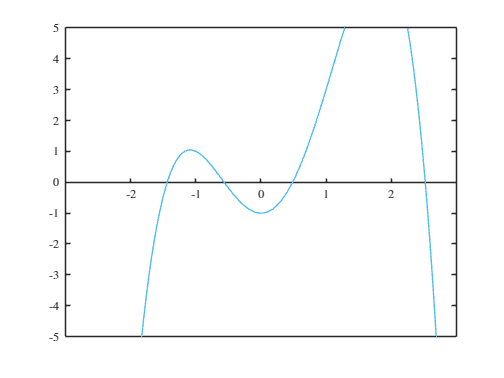


figure
hold on
fplot( transpose( m_coeff ) * M, [-3 3], Color="k" )
fplot( transpose( l_coeff ) * L, [-3 3], SeriesIndex=1 )
fplot( transpose( b_coeff ) * B, [-3 3], SeriesIndex=2 )
fplot( transpose( p_coeff ) * P, [-3 3], SeriesIndex=3 )
fplot( transpose( t_coeff ) * T, [-3 3], SeriesIndex=4 )
fplot( transpose( lp_coeff ) * LP, [-3 3], SeriesIndex=5 )
fplot( transpose( lt_coeff ) * LT, [-3 3], SeriesIndex=6 )
ax = gca;
ax.YLim = [-5 5];
ax.XAxisLocation = "origin";

## Integration

clear
close all

x = sym( "x" );
a = sym( pi / 2 );
deriv = 1;

f = sin( x )

$$f = \sin\left(x\right)$$

df = diff( f, x, deriv )

$$df = \cos\left(x\right)$$

g = cos( x )

$$g = \cos\left(x\right)$$

dg = diff( g, x, deriv )

$$dg = -\sin\left(x\right)$$


subs(df - dg, x, a )

$$ans = 1$$

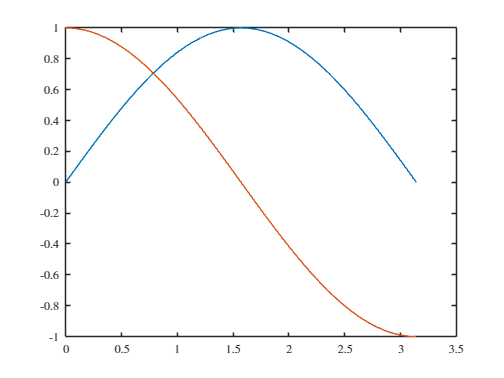


figure
hold on
fplot( f, [0 pi] )
fplot( g, [0 pi] )


tol = sym( logspace( -12, 0, 13 ) );
for ii = 1 : length( tol )
    exact(ii,1) = subs( sqrt( f - g )^2, x, a );
    approx(ii,1) = simplify( int( sqrt( f - g )^2, [a - tol(ii) / 2, a + tol(ii) / 2] ) ) / tol(ii);
    error(ii,1) = simplify( exact(ii) - approx(ii) );
end
% vpa( exact )

$$ans = \left[\begin{array}{c} 1.0\\ 1.0\\ 1.0\\ 1.0\\ 1.0\\ 1.0\\ 1.0\\ 1.0\\ 1.0\\ 1.0\\ 1.0\\ 1.0\\ 1.0 \end{array}\right]$$

% vpa( approx )

$$ans = \left[\begin{array}{c} 0.99999999999999999999999995833333\\ 0.99999999999999999999999583333333\\ 0.99999999999999999999958333333333\\ 0.99999999999999999995833333333333\\ 0.99999999999999999583333333333333\\ 0.99999999999999958333333333333339\\ 0.99999999999995833333333333385417\\ 0.99999999999583333333333854166667\\ 0.99999999958333333338541666666357\\ 0.99999995833333385416666356646826\\ 0.99999583333854166356646933042579\\ 0.99958338541356657589730001690981\\ 0.95885107720840600054657587043114 \end{array}\right]$$

% vpa( error )

$$ans = \left[\begin{array}{c} 0.000000000000000000000000041666666666666732364142933147693\\ 0.0000000000000000000000041666666666666668079295622553845\\ 0.0000000000000000000004166666666666666666502898172078\\ 0.00000000000000000004166666666666666666594733668236\\ 0.0000000000000000041666666666666666614583743681196\\ 0.00000000000000041666666666666661458333315907308\\ 0.000000000000041666666666666145833333333308724\\ 0.0000000000041666666666614583333333364333025\\ 0.0000000004166666666145833333364335317459\\ 0.000000041666666145833336433531735267168\\ 0.0000041666614583364335306695742084943\\ 0.00041661458643342410269998309019321\\ 0.041148922791593999453424129568857 \end{array}\right]$$

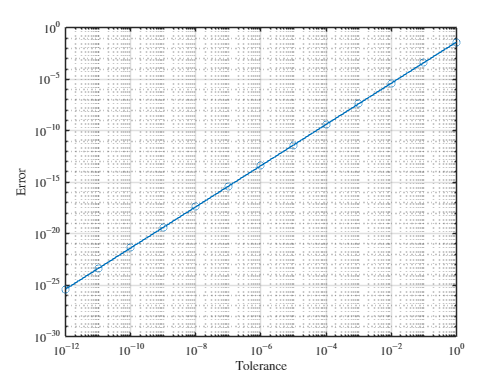


figure
plot( tol, error, Marker="o" )
ax = gca;
ax.XScale = "log";
ax.YScale = "log";
ax.XGrid = "on";
ax.YGrid = "on";
xlabel( "Tolerance" )
ylabel( "Error" )

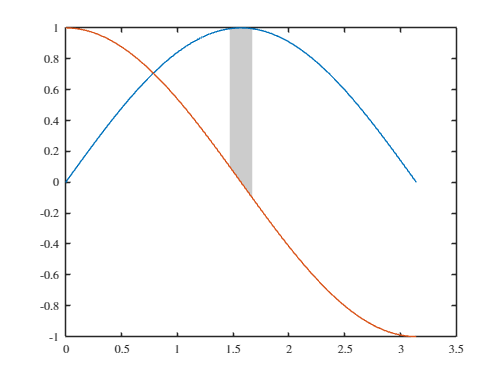


figure
cmap = lines;
hold on
xd = transpose( linspace( a - 0.1, a + 0.1, 1e3 ) );
yhigh = double( subs( max( f, g ), x, xd ) );
ylow = double( subs( min( f, g ), x, xd ) );
fill( [xd; flipud( xd )], [yhigh; flipud( ylow )], [0.8 0.8 0.8], LineStyle="none" )
fplot( f, [0 pi] )
fplot( g, [0 pi] )

function scaled_arrow( ax, arrow_center, arrow_slope, arrow_length )
cx = arrow_center(1);
cy = arrow_center(2);
[coord_x, coord_y] = coord2norm( ax, [cx - ( arrow_length / 2 ) * cos( tan( arrow_slope ) ), cx + ( arrow_length / 2 ) * cos( tan( arrow_slope ) )], [cy - ( arrow_length / 2 ) * sin( tan( arrow_slope ) ), cy + ( arrow_length / 2 ) * sin( tan( arrow_slope ) )] );
annotation( "textarrow", coord_x, coord_y )
end

function T = TaylorExpansion( fun, a, order )
x = symvar( fun );
T(x) = sym( 0 );
for n = 0: order
    T = T + simplify( ( subs( diff( fun, x, n ), a ) / factorial( n ) ) * ( x - a ) ^ n );
end
end

function d = dirac_limit( x, a, b )
d = 1/( abs(a) * sqrt(sym(pi)) ) * exp( -((x-b)/a)^2);
end